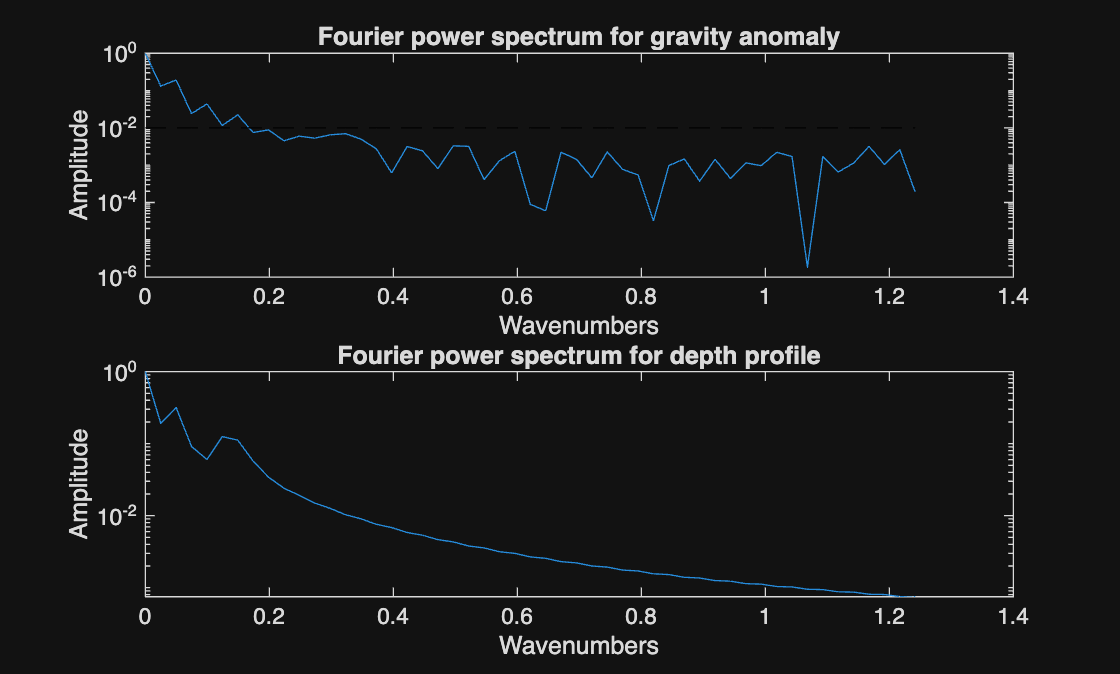

ADAPTIVE FOURIER COEFFICIENT SELECTION


Energy retention %            = 99.00


Max allowed coefficients       = 51


Error threshold (RMSE/RMS)     = 0.0500 (5.00% of RMS)


Saturation threshold           = 0.0200 (2.0% relative improvement)


Required saturation steps      = 2



--- Phase 1: Energy Criterion ---


Initial N0 (energy criterion)    = 3


Actual retained energy at N0     = 99.66 %


RMS of observed gravity anomaly  = 23.0586 mGal



--- Phase 2: Evaluation at N0 ---


RMSE at N0 = 3                 = 1.9314 mGal


Error ratio (RMSE/RMS) at N0    = 0.0838 (8.38% of RMS)


User-defined threshold           = 0.0500 (5.00% of RMS)



--- Case B: N0 INSUFFICIENT, searching UPWARD for better reconstruction ---


Strategy: Add coefficients until:


  [1] Error <= 5.00% of RMS, OR


  [2] 2 consecutive steps with < 2.0% RMSE improvement (saturation), OR


  [3] Max limit (51 coefficients) reached


N = 4: RMSE=1.7980, ErrorRatio=0.0780 (7.80%), Improvement=0.0691 (6.91%)

 -> Continue searching (significant improvement)


N = 5: RMSE=1.1409, ErrorRatio=0.0495 (4.95%), Improvement=0.3654 (36.54%)

 -> ACCEPTED (error threshold satisfied)


FINAL RESULTS (Summary)


Selected number of coefficients = 5


  -> QPSO will optimise 11 parameters (2 x 5 + 1)


Final reconstruction RMSE       = 1.1409 mGal


Final Error Ratio (RMSE/RMS)    = 0.0495 (4.95% of RMS)


Correlation coefficients of power spectrum for gravity and depth profile is 0.980135


Iter 1 | contractionCoeff=0.750 | Best Cost = 29.6617134
Iter 2 | contractionCoeff=0.750 | Best Cost = 11.5783184
Iter 3 | contractionCoeff=0.750 | Best Cost = 11.5783184
Iter 4 | contractionCoeff=0.750 | Best Cost = 7.8149419
Iter 5 | contractionCoeff=0.750 | Best Cost = 7.7910245
Iter 6 | contractionCoeff=0.750 | Best Cost = 7.7910245
Iter 7 | contractionCoeff=0.750 | Best Cost = 7.7910245
Iter 8 | contractionCoeff=0.750 | Best Cost = 7.7910245
Iter 9 | contractionCoeff=0.750 | Best Cost = 7.2199817
Iter 10 | contractionCoeff=0.750 | Best Cost = 6.4365638
Iter 11 | contractionCoeff=0.750 | Best Cost = 4.8511986
Iter 12 | contractionCoeff=0.750 | Best Cost = 3.3739716
Iter 13 | contractionCoeff=0.750 | Best Cost = 3.3739716
Iter 14 | contractionCoeff=0.750 | Best Cost = 3.3739716
Iter 15 | contractionCoeff=0.750 | Best Cost = 3.3739716
Iter 16 | contractionCoeff=0.750 | Best Cost = 3.0989769
Iter 17 | contractionCoeff=0.750 | Best Cost = 3.0989769
Iter 18 | contractionCoeff=0.750 | Be

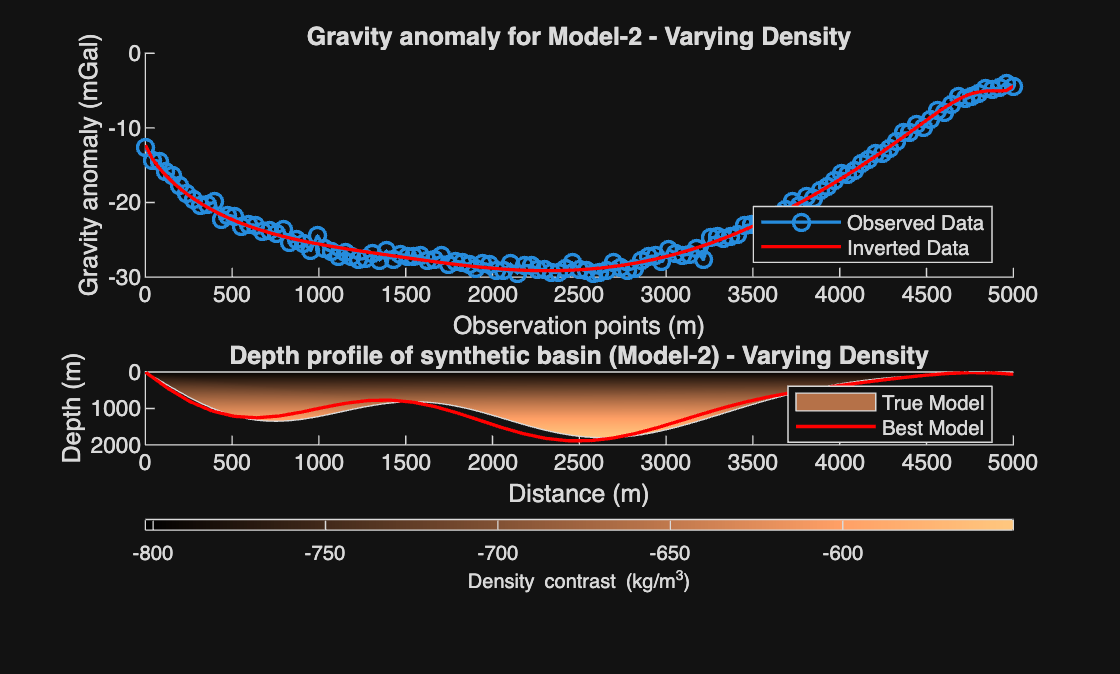

RMSE in gravity field=0.020799, and in depth profile=0.070721


True RMSE in gravity field=0.020415


Relative misfit for Best model=2.296675


Relative misfit for True model=2.256567


% ***************************************************************
% *** Matlab code for synthetic model-2 with varying density distribution.
% *** Uses QPSO for optimization, with adaptive Fourier coefficient
% *** selection (data-driven choice of number of parameters, instead
% *** of a fixed manual value).
% *** UPDATED: Adaptive Fourier selection with user-defined RMSE/RMS
% *** threshold, downward/upward search, and saturation detection
% % *** NOISE: 0*sqrt(0.25) = 0.
% ***************************************************************
clear; clc; close all;


%%%%    Creation of Synthetic Model and finding Gravity anomaly     %%%%
% peaks(200) is MATLAB's built-in test surface. Two rows are combined and
% offset to build a more complex, irregular basin shape than a single-peak
% profile would provide.
peaksSurface = peaks(200);
combinedPeaks = ((peaksSurface(51*2+1,:)))*450 + abs(((peaksSurface(9*2+1,:)))*450);
syntheticDepthRaw = combinedPeaks(74:200);

% Legendre-Gauss quadrature nodes and weights for numerical integration
% of the line-integral forward gravity model (10-point quadrature)
[quadNodes,quadWeights] = lgwt(10,0,1);

% Synthetic observation points evenly spaced along the surface (127 points)
obsX = linspace(0,5000,length(syntheticDepthRaw));
trueDepth = syntheticDepthRaw;
obsZ = 0;  % All observations at the surface (z = 0)

% Depth-dependent density distribution: exponential compaction law
% Models how sediment density increases with burial depth
% rho(z) = -0.38 - 0.42*exp(-0.5*z*10^-3) [g/cm^3], multiplied by 1000 for kg/m^3
densityFcn = @(z)(-0.38-0.42*exp(-0.5*z*10^-3))*1000;

% Closed polygon representing the 2-D cross-section of the basin
% Required by the forward gravity modelling routine
polyX = [obsX obsX(end) 0];
polyZ = [trueDepth 0 0];

% Forward gravity anomaly for the true (varying-density) model
gravAnomalyNoisy = variable_density_gravity(obsX,obsZ,polyX,polyZ,densityFcn,quadNodes,quadWeights);
gravAnomalyTrue = gravAnomalyNoisy;  % Keep a noise-free copy for later comparison

% Add Gaussian noise: zero mean, standard deviation = sqrt(0.25)
% This simulates imperfect field measurements
gravAnomalyNoisy = gravAnomalyNoisy + 0*sqrt(0.25).*randn(size(gravAnomalyNoisy))+0;

%%%% Fourier Spectral Analysis %%%%
% The gravity anomaly and depth profile are extended by mirroring to make
% them periodic — a requirement for Fourier series expansion
extIndex = 1:2*length(gravAnomalyNoisy);
halfPeriod = (extIndex(end)-extIndex(1))/2;

gravDataExt = [gravAnomalyNoisy fliplr(gravAnomalyNoisy)];  % Periodic gravity data
depthDataExt = [trueDepth fliplr(trueDepth)];                % Periodic depth data

% Pre-allocate arrays for the first 100 Fourier coefficients
gravCosCoeff=zeros(1,100); gravSinCoeff=zeros(1,100);
depthCosCoeff=zeros(1,100); depthSinCoeff=zeros(1,100);
gravAmplitude=zeros(1,101); depthAmplitude=zeros(1,101);
waveNumber=zeros(1,101);

% Compute the first 100 Fourier coefficients (cosine and sine terms) for
% both the gravity anomaly and the depth profile using numerical
% integration (trapezoidal rule). The amplitude spectrum tells us how much
% spectral power each harmonic carries — the basis for our adaptive selection.
for harmonicIdx=1:100
  %--- Fourier coefficients for the gravity field ---
  gravCosTerm = gravDataExt.*cos(harmonicIdx*pi*extIndex/halfPeriod);
  gravCosCoeff(harmonicIdx) = (1/halfPeriod)*trapz(extIndex,gravCosTerm);
  gravSinTerm = gravDataExt.*sin(harmonicIdx*pi*extIndex/halfPeriod);
  gravSinCoeff(harmonicIdx) = (1/halfPeriod)*trapz(extIndex,gravSinTerm);
  gravAmplitude(harmonicIdx+1) = sqrt((gravCosCoeff(harmonicIdx))^2+(gravSinCoeff(harmonicIdx))^2);

  %--- Fourier coefficients for the depth profile ---
  depthCosTerm = depthDataExt.*cos(harmonicIdx*pi*extIndex/halfPeriod);
  depthCosCoeff(harmonicIdx) = (1/halfPeriod)*trapz(extIndex,depthCosTerm);
  depthSinTerm = depthDataExt.*sin(harmonicIdx*pi*extIndex/halfPeriod);
  depthSinCoeff(harmonicIdx) = (1/halfPeriod)*trapz(extIndex,depthSinTerm);
  depthAmplitude(harmonicIdx+1) = sqrt((depthCosCoeff(harmonicIdx))^2+(depthSinCoeff(harmonicIdx))^2);

  waveNumber(harmonicIdx+1) = harmonicIdx*pi/halfPeriod;
end

% Normalise Fourier coefficients so the spectral peak amplitude = 1
% This makes it easier to compare and apply thresholds consistently
gravAmplitude(1) = abs((1/halfPeriod)*trapz(extIndex,gravDataExt));  % DC (zero-frequency) term
gravAmplitude = gravAmplitude./max(gravAmplitude);
depthAmplitude(1) = abs((1/halfPeriod)*trapz(extIndex,depthDataExt));
depthAmplitude = depthAmplitude./max(depthAmplitude);
waveNumber(1) = 0;

% Plot the Fourier power spectrum of gravity anomaly and depth profile
% The dashed line (10^-2) serves as a visual reference threshold
figure(1)
subplot(2,1,1)
semilogy(waveNumber(1:51),gravAmplitude(1:51))
hold on
semilogy(waveNumber(1:51),10^-2.*ones(51,1),'k--')
title('Fourier power spectrum for gravity anomaly')
xlabel('Wavenumbers')
ylabel('Amplitude')

subplot(2,1,2)
semilogy(waveNumber(1:51),depthAmplitude(1:51))
title('Fourier power spectrum for depth profile')
xlabel('Wavenumbers')
ylabel('Amplitude')

%%% ================================================================
%%% ADAPTIVE FOURIER COEFFICIENT SELECTION
%%% ================================================================
%%% CONCEPT:
%%% The depth profile is parameterised by only the first N Fourier terms
%%% (a truncated series). This acts as an implicit low-pass filter —
%%% keeping the low-frequency geological signal and discarding high-frequency
%%% noise. Too few terms leads to under-fitting; too many terms leads to
%%% fitting noise as if it were signal.
%%%
%%% ALGORITHM OVERVIEW:
%%% Step 1: Find initial guess N0 from energy criterion (99% spectral energy)
%%% Step 2: Calculate RMSE/RMS ratio (errorRatio) at N0
%%% Step 3:
%%%   Case A — If errorRatio ≤ userThreshold: search DOWNWARD (N0-1, N0-2, ...)
%%%            to find the smallest N that still satisfies the threshold.
%%%   Case B — If errorRatio > userThreshold: search UPWARD (N0+1, N0+2, ...)
%%%            until either: (a) error threshold is achieved,
%%%            (b) saturation is detected (consecutive steps with < 2%
%%%                relative RMSE improvement), or
%%%            (c) the maximum allowed coefficient limit is reached.
%%%
%%% NOTE: Model-2 uses depth-dependent density (exponential compaction law),
%%% unlike Model-1 which uses constant density. The adaptive selection
%%% algorithm itself is identical — it depends only on the gravity data's
%%% Fourier spectrum and reconstruction quality.
%%% ================================================================

%%% ================================================================
%%% USER-DEFINED PARAMETERS
%%% ================================================================

% Spectral energy retention percentage for the initial guess N0.
% 99% means the first N coefficients capture 99% of the total spectral power.
% Typical range: 95–99.5 (higher values give more coefficients initially).
energyPercent = 99;

% Maximum allowed Fourier coefficients (safety upper bound).
% More parameters means higher computational cost for QPSO.
% 51 corresponds to the Nyquist limit for 127-point data.
maxCoeffUser = 51;

% Acceptable RMSE/RMS ratio (reconstruction quality threshold).
% 0.05 means the RMSE must be ≤ 5% of the RMS of the observed gravity.
% Lower values require a stricter fit (suitable for noise-free data);
% higher values relax the fit (suitable for noisy data).
% Typical range: 0.01 (noise-free) to 0.10 (noisy).
errorThreshold = 0.05;

% Relative RMSE improvement below which we consider the improvement "saturated".
% 0.02 = 2% relative improvement. If (prevRMSE - currRMSE)/prevRMSE < 2%,
% adding more coefficients gives negligible benefit.
% Typical range: 0.01–0.05.
saturationThreshold = 0.02;

% Number of consecutive saturated steps required to confirm saturation.
% This avoids false detection from a single anomalous step.
% 2 means two consecutive steps must each show improvement < saturationThreshold.
% Typical range: 2–3.
requiredSatSteps = 2;

% Display the user-defined parameter settings
fprintf('\n');
fprintf('========================================================\n');
fprintf('ADAPTIVE FOURIER COEFFICIENT SELECTION\n');
fprintf('========================================================\n');
fprintf('Energy retention %%            = %.2f\n', energyPercent);
fprintf('Max allowed coefficients       = %d\n', maxCoeffUser);
fprintf('Error threshold (RMSE/RMS)     = %.4f (%.2f%% of RMS)\n', errorThreshold, errorThreshold*100);
fprintf('Saturation threshold           = %.4f (%.1f%% relative improvement)\n', saturationThreshold, saturationThreshold*100);
fprintf('Required saturation steps      = %d\n', requiredSatSteps);
fprintf('========================================================\n');

%%% ================================================================
%%% PHASE 1: Find Initial N0 from the Energy Criterion
%%% ================================================================
% Purpose: Determine the minimum number of Fourier coefficients needed
% to capture the user-specified percentage of total spectral energy.
% Method: Compute the cumulative energy ratio and find the first N
% where cumulativeEnergy >= energyPercent/100.

coeffEnergy = gravAmplitude(1:51).^2;          % Energy of each coefficient
totalEnergy = sum(coeffEnergy);                 % Total spectral energy
cumulativeEnergy = cumsum(coeffEnergy) ./ totalEnergy;  % Cumulative energy ratio
N0 = find(cumulativeEnergy >= energyPercent/100, 1, 'first');  % First N satisfying criterion

fprintf('\n--- Phase 1: Energy Criterion ---\n');
fprintf('Initial N0 (energy criterion)    = %d\n', N0);
fprintf('Actual retained energy at N0     = %.2f %%\n', cumulativeEnergy(N0)*100);

%%% ================================================================
%%% PHASE 2: Evaluate Reconstruction Quality at N0
%%% ================================================================

% Compute RMS of the observed gravity for normalisation
% RMS is a statistically robust measure of signal magnitude, preferred
% over max-min range because it is less sensitive to outliers.
rmsGravity = rms(gravAnomalyNoisy);
fprintf('RMS of observed gravity anomaly  = %.4f mGal\n', rmsGravity);

% Evaluate reconstruction error at N0 using the helper function
[rmseN0, errorRatioN0] = computeReconstructionError(N0, gravCosCoeff, gravSinCoeff, ...
    extIndex, halfPeriod, gravDataExt, rmsGravity);

fprintf('\n--- Phase 2: Evaluation at N0 ---\n');
fprintf('RMSE at N0 = %d                 = %.4f mGal\n', N0, rmseN0);
fprintf('Error ratio (RMSE/RMS) at N0    = %.4f (%.2f%% of RMS)\n', errorRatioN0, errorRatioN0*100);
fprintf('User-defined threshold           = %.4f (%.2f%% of RMS)\n', errorThreshold, errorThreshold*100);

%%% ================================================================
%%% PHASE 3: Adaptive Search Algorithm
%%% ================================================================
% The decision at N0 determines the search direction:
%   errorRatioN0 ≤ errorThreshold  →  CASE A: try to REDUCE (downward search)
%   errorRatioN0 > errorThreshold  →  CASE B: need MORE (upward search)

if errorRatioN0 <= errorThreshold
    
    % ===== CASE A: N0 is acceptable — try to REDUCE the number of coefficients =====
    % If the error is already acceptable at N0, we may be able to use even
    % fewer coefficients. A smaller model (fewer parameters) is preferred by
    % Occam's razor — simpler explanations are better.
    % Search downward N0-1, N0-2, ..., 1; accept as long as errorRatio ≤ threshold;
    % stop as soon as the threshold is exceeded.
    
    fprintf('\n--- Case A: N0 ACCEPTABLE, searching DOWNWARD for smaller model ---\n');
    fprintf('Strategy: Reduce coefficients as long as error stays within %.2f%% of RMS\n', errorThreshold*100);
    
    bestCount = N0;  % Initialise with N0 (already known to be acceptable)
    
    for N = N0-1 : -1 : 1
        [rmseN, errorRatioN] = computeReconstructionError(N, gravCosCoeff, gravSinCoeff, ...
            extIndex, halfPeriod, gravDataExt, rmsGravity);
        
        if errorRatioN <= errorThreshold
            bestCount = N;  % Accept this smaller N
            fprintf('N = %d: RMSE=%.4f, ErrorRatio=%.4f (%.2f%%) -> ACCEPTED (smaller model works)\n', ...
                N, rmseN, errorRatioN, errorRatioN*100);
        else
            % Error jumped above threshold — this N is too small, stop here
            fprintf('N = %d: RMSE=%.4f, ErrorRatio=%.4f (%.2f%%) -> REJECTED (threshold exceeded, too few coeffs)\n', ...
                N, rmseN, errorRatioN, errorRatioN*100);
            break;
        end
    end
    
    fprintf('\n>>> FINAL SELECTION (Case A - Minimum acceptable model): %d coefficients\n', bestCount);
    
else
    
    % ===== CASE B: N0 is insufficient — need MORE coefficients =====
    % The energy criterion did not provide enough coefficients; gravity
    % reconstruction quality is unacceptable at N0. For varying-density
    % models, more Fourier terms may be needed to adequately capture the
    % gravity signal.
    % Search upward N0+1, N0+2, ..., maxCoeffUser with three stopping conditions
    % (whichever occurs first):
    %   [1] errorRatio ≤ threshold  →  quality achieved, accept this N
    %   [2] Saturation detected     →  consecutive requiredSatSteps with
    %                                  improvement < saturationThreshold
    %   [3] N > maxCoeffUser        →  safety limit reached, issue warning
    
    fprintf('\n--- Case B: N0 INSUFFICIENT, searching UPWARD for better reconstruction ---\n');
    fprintf('Strategy: Add coefficients until:\n');
    fprintf('  [1] Error <= %.2f%% of RMS, OR\n', errorThreshold*100);
    fprintf('  [2] %d consecutive steps with < %.1f%% RMSE improvement (saturation), OR\n', ...
        requiredSatSteps, saturationThreshold*100);
    fprintf('  [3] Max limit (%d coefficients) reached\n', maxCoeffUser);
    
    bestCount = N0;           % Fallback value if nothing else selected
    prevRMSE = rmseN0;        % RMSE at N0 — reference for improvement calculation
    saturationCount = 0;      % Counter for consecutive saturated steps
    foundAcceptable = false;  % Flag: was the error threshold ever satisfied?
    
    for N = N0+1 : maxCoeffUser
        
        [rmseN, errorRatioN] = computeReconstructionError(N, gravCosCoeff, gravSinCoeff, ...
            extIndex, halfPeriod, gravDataExt, rmsGravity);
        
        % Relative improvement in RMSE: (old - new) / old
        % Positive = improvement (RMSE decreasing), negative = degradation
        relativeImprovement = (prevRMSE - rmseN) / prevRMSE;
        
        fprintf('N = %d: RMSE=%.4f, ErrorRatio=%.4f (%.2f%%), Improvement=%.4f (%.2f%%)', ...
            N, rmseN, errorRatioN, errorRatioN*100, relativeImprovement, relativeImprovement*100);
        
        % --- Check [1]: Has the error threshold been satisfied? ---
        if errorRatioN <= errorThreshold
            bestCount = N;
            foundAcceptable = true;
            fprintf(' -> ACCEPTED (error threshold satisfied)\n');
            break;
        end
        
        % --- Check [2]: Is saturation occurring? ---
        % Saturation means the RMSE improvement has become negligible —
        % adding more coefficients is pointless.
        if relativeImprovement < saturationThreshold
            saturationCount = saturationCount + 1;
            fprintf(' -> SATURATED (improvement < %.1f%%) [Step %d/%d]\n', ...
                saturationThreshold*100, saturationCount, requiredSatSteps);
            
            if saturationCount >= requiredSatSteps
                % Confirmed: last requiredSatSteps steps all showed negligible improvement.
                % Revert to where saturation began: N - requiredSatSteps.
                bestCount = N - requiredSatSteps;
                fprintf('\n>>> SATURATION CONFIRMED at N=%d (%d consecutive steps with improvement < %.1f%%)\n', ...
                    N, requiredSatSteps, saturationThreshold*100);
                fprintf('    Adding more coefficients gives negligible benefit — stopping here.\n');
                fprintf('>>> FINAL SELECTION (Case B - Saturation): %d coefficients\n', bestCount);
                break;
            end
        else
            saturationCount = 0;  % Significant improvement — reset the counter
            fprintf(' -> Continue searching (significant improvement)\n');
        end
        
        prevRMSE = rmseN;  % Update for the next iteration's improvement calculation
        
        % --- Check [3]: Have we reached the user-defined maximum? ---
        if N == maxCoeffUser
            if ~foundAcceptable
                warning('Reached max user-defined coefficients (%d) without meeting error threshold (%.4f).', ...
                    maxCoeffUser, errorThreshold);
                fprintf('    Current error ratio: %.4f (%.2f%% of RMS)\n', errorRatioN, errorRatioN*100);
            end
            fprintf('>>> FINAL SELECTION (Case B - Max limit reached): %d coefficients\n', maxCoeffUser);
            bestCount = N;
        end
    end
    
    % Safety fallback (should not normally be triggered)
    if bestCount == N0 && ~foundAcceptable
        fprintf('\n>>> FINAL SELECTION (Case B - Fallback to N0): %d coefficients\n', bestCount);
    end
end

%%% ================================================================
%%% FINAL SELECTION: Verify and Report
%%% ================================================================

numCoefficients = bestCount;

% Verify the quality of the final selection
[rmseFinal, errorRatioFinal] = computeReconstructionError(numCoefficients, gravCosCoeff, gravSinCoeff, ...
    extIndex, halfPeriod, gravDataExt, rmsGravity);

fprintf('\n========================================================\n');
fprintf('FINAL RESULTS (Summary)\n');
fprintf('========================================================\n');
fprintf('Selected number of coefficients = %d\n', numCoefficients);
fprintf('  -> QPSO will optimise %d parameters (2 x %d + 1)\n', 2*numCoefficients+1, numCoefficients);
fprintf('Final reconstruction RMSE       = %.4f mGal\n', rmseFinal);
fprintf('Final Error Ratio (RMSE/RMS)    = %.4f (%.2f%% of RMS)\n', errorRatioFinal, errorRatioFinal*100);
fprintf('========================================================\n\n');

gravObserved = gravAnomalyNoisy;

% Correlation between gravity and depth power spectra — a diagnostic check.
% The two should be strongly correlated if the parameterisation captures
% the true depth-to-gravity relationship.
corrCoeff = corrcoef(gravAmplitude,depthAmplitude);
fprintf('Correlation coefficients of power spectrum for gravity and depth profile is %f\n',corrCoeff(1,2))

%%%% Construct the Fourier transformation matrix %%%%
% This matrix maps a vector of Fourier coefficients (the unknowns QPSO
% will optimise) into a depth profile in the physical (space) domain.
% Column 1                          = DC (constant) term
% Columns 2 to numCoefficients+1    = Cosine terms
% Columns numCoefficients+2 to end  = Sine terms
matIndex = 1:2*length(obsX);
matHalfPeriod = (matIndex(end)-matIndex(1))/2;
for rowIdx=1:length(matIndex)
    cosCount=0; sinCount=0;
    for colIdx=1:2*numCoefficients+1
        if colIdx==1
            fourierMatrix(rowIdx,colIdx)=(1/2);  % DC term
        elseif colIdx>1 && colIdx<=numCoefficients+1
            cosCount=cosCount+1;
            fourierMatrix(rowIdx,colIdx)=cos(cosCount*pi*matIndex(rowIdx)/matHalfPeriod);  % Cosine
        else
            sinCount=sinCount+1;
            fourierMatrix(rowIdx,colIdx)=sin(sinCount*pi*matIndex(rowIdx)/matHalfPeriod);  % Sine
        end
    end
end

%% ================= QPSO MAIN RUN ==================
% Cost function = normalised misfit between observed and reconstructed gravity
% plus a large penalty (weight = 1000) if the reconstructed depth profile
% violates the physical lower/upper depth bounds.
costFcn = @(paramVec) costFunction(paramVec,gravObserved,fourierMatrix,quadNodes,quadWeights) + ...
    1000*(lowerBoundPenalty(paramVec,fourierMatrix)+upperBoundPenalty(paramVec,fourierMatrix));

numParams  = (2*numCoefficients+1);  % Number of unknowns (DC + cos + sin terms)
maxIterations = 300;                 % Maximum QPSO iterations per run
swarmSize  = 100;                    % Number of particles in the swarm

% Run QPSO multiple independent times to build an ensemble of solutions.
% This ensemble is later used to pick the single best model and to assess
% uncertainty/equivalence via PCA.
costEnsemble=[]; varEnsemble=[];
numRuns=5;  % 5 independent runs for robust ensemble statistics

for runIdx=1:numRuns
    [bestVarRun, bestCostRun, iterCountRun, errorEnergyRun, allVarRun, allCostRun] = ...
        QPSO(costFcn, numParams, maxIterations, swarmSize);
    
    % Store this run's best result and its full iteration history
    bestCostPerRun(runIdx)=bestCostRun;
    bestVarPerRun(:,runIdx)=bestVarRun;
    errorEnergyPerRun(:,runIdx)=errorEnergyRun';
    costEnsemble=[costEnsemble allCostRun];  % Pool of costs across ALL iterations of ALL runs
    varEnsemble=[varEnsemble allVarRun];     % Corresponding pool of parameter vectors
end

% Select the overall best model across the independent runs
[minCost,minCostIdx]=min(bestCostPerRun);
bestVarFinal=(squeeze(bestVarPerRun(:,minCostIdx)))';       % Best Fourier coefficients
bestErrorFinal=(squeeze(errorEnergyPerRun(:,minCostIdx)))'; % Convergence history

%% ============ Plotting Results ============
bestCoeffVector=bestVarFinal';
reconX=linspace(min(obsX),max(obsX),40);            % 40 points for smooth polygon plotting
depthEvalFull=(fourierMatrix*bestCoeffVector)';     % Depth at all obsX (mirrored/periodic)
depthEvalHalf=depthEvalFull(1:length(depthEvalFull)/2);  % Physical half only
depthRecon=spline(obsX,depthEvalHalf,reconX);       % Spline-interpolate to 40 points

% Close the reconstructed depth profile into a polygon for forward modelling
reconPolyX=[reconX max(reconX) min(reconX)];
reconPolyZ=[depthRecon 0 0];
gravRecon=variable_density_gravity(obsX,0,reconPolyX,reconPolyZ,densityFcn,quadNodes,quadWeights);

figure(2)
% --- Lower subplot: Depth profile (true vs. inverted) ---
subplot(2,1,2); hold on
patchX=[0 obsX obsX(end)];
patchZ=[0 trueDepth 0];
% Patch plot coloured by local density contrast (shows depth-dependent density)
patch(patchX,patchZ,densityFcn(patchZ)); colormap copper
plot(reconX,depthRecon,'r','LineWidth',1.25)
set(gca,'Ydir','reverse')  % Depth increases downward
cb = colorbar('location','southoutside');
cb.Label.String = 'Density contrast (kg/m^3)';
xlabel('Distance (m)'); ylabel('Depth (m)')
legend('True Model','Best Model','location','southeast')
title('Depth profile of synthetic basin (Model-2) - Varying Density')

% --- Upper subplot: Gravity anomaly (observed vs. inverted) ---
subplot(2,1,1); hold on
plot(obsX,gravObserved,'-o','LineWidth',1.25)
plot(obsX,gravRecon,'r','LineWidth',1.25)
xlabel('Observation points (m)'); ylabel('Gravity anomaly (mGal)')
title('Gravity anomaly for Model-2 - Varying Density')
legend('Observed Data','Inverted Data','location','southeast')

%% RMSE (Goodness-of-Fit Metrics)
numObs=length(gravObserved);
numDepthPts=length(trueDepth);

% Normalised RMSE between observed (noisy) and inverted gravity
rmseGravity=sqrt(sum((gravObserved-gravRecon).^2)/numObs)/(max(gravObserved)-min(gravObserved));
% Normalised RMSE between observed (noisy) and true (noise-free) gravity
% This is a benchmark: it measures how much the noise itself deviates from the true signal
rmseTrueGravity=sqrt(sum((gravObserved-gravAnomalyTrue).^2)/numObs)/(max(gravObserved)-min(gravObserved));
% Normalised RMSE between true and inverted depth — the key accuracy metric
rmseDepth=sqrt(sum((trueDepth-depthEvalHalf).^2)/numDepthPts)/(max(trueDepth)-min(trueDepth));

fprintf('RMSE in gravity field=%f, and in depth profile=%f\n',rmseGravity,rmseDepth)
fprintf('True RMSE in gravity field=%f\n',rmseTrueGravity)

%% ============ PCA / Uncertainty Appraisal ============
% Gravity inversion is inherently non-unique — many different depth models
% can explain the observed data almost equally well. Here we collect all
% models (across all QPSO iterations/runs) whose misfit cost is ≤ 40 and
% use PCA to visualise the spread of these "equivalent" models in a reduced
% 2-D space, along with the locations of the best-fit and true models.

acceptedCount=0;
acceptedModels = [];  % Pool of accepted (low-misfit) depth models
acceptedCost = [];    % Their corresponding misfit costs

for idx=1:length(costEnsemble)
    if costEnsemble(idx) <= 40  % Misfit threshold for "acceptable" models
        acceptedCount=acceptedCount+1;
        acceptedCost(1,acceptedCount)=costEnsemble(1,idx);
        reconModelFull=fourierMatrix*squeeze(varEnsemble(:,idx));
        acceptedModels(:,acceptedCount)=reconModelFull(1:length(reconModelFull)/2);
    end
end

% Only run PCA if we have at least 2 accepted models (covariance/PCA is undefined otherwise)
if exist('acceptedModels', 'var') && size(acceptedModels, 2) > 1
    % Reduce the high-dimensional model ensemble to its first two principal components
    [pcaScores,eigenValues,eigenVectors]=pca_reduction(acceptedModels);
    pc1=pcaScores(1,:); pc2=pcaScores(2,:);
    
    % Build a misfit "topography" over the PCA plane by interpolating
    % the known misfit cost of each accepted model onto a regular grid
    [gridPC1,gridPC2]=meshgrid(min(pc1):10:max(pc1), min(pc2):10:max(pc2));
    misfitGrid=griddata(pc1,pc2,acceptedCost,gridPC1,gridPC2);

    figure(3)
    contourf(gridPC1,gridPC2,misfitGrid,10)
    colormap jet
    colorbar

    trueModelVector=trueDepth';
    % Relative misfit of the true (noise-free) model vs. the noisy data
    trueMisfit=(norm(gravAnomalyTrue-gravAnomalyNoisy)/norm(gravAnomalyTrue))*100;

    % The single best (lowest-misfit) model among the accepted ensemble
    [bestMisfit, bestIdx] = min(acceptedCost);
    bestAcceptedModel = acceptedModels(:,bestIdx);

    % Project the best model and the true model into the same PCA space
    % (mean-centred using the ensemble's own mean)
    bestModelPCA=eigenVectors*(bestAcceptedModel-mean(acceptedModels,2));
    trueModelPCA=eigenVectors*(trueModelVector-mean(acceptedModels,2));

    % Overlay the best-fit and true model locations on the misfit topography
    hold on
    plot(bestModelPCA(1),bestModelPCA(2),'r^','LineWidth',4)
    plot(trueModelPCA(1),trueModelPCA(2),'gv','LineWidth',4)
    xlabel('Principal component 1')
    ylabel('Principal component 2')
    title('Relative Misfit in PCA space Model-2 (varying density), noisy data')
    legend('Equivalence function topography','Best model','True model','Location','best')
    fprintf('Relative misfit for Best model=%f\n',bestMisfit)
    fprintf('Relative misfit for True model=%f\n',trueMisfit)
else
    fprintf('Not enough data for PCA analysis\n');
end


%%%% ================================================================
%%%% ALL LOCAL FUNCTIONS (at the end of the script, all with 'end')
%%%% ================================================================

function [rmseVal, errorRatio] = computeReconstructionError(N, gravCosCoeff, gravSinCoeff, ...
    extIndex, halfPeriod, gravOriginal, rmsGravity)
% COMPUTERECONSTRUCTIONERROR  Reconstruct gravity using N Fourier coefficients
% and compute reconstruction quality metrics (RMSE and RMSE/RMS ratio).
    dcTerm = (1/halfPeriod) * trapz(extIndex, gravOriginal);
    gravRecon = dcTerm/2 * ones(size(extIndex));
    for k = 1:N-1
        gravRecon = gravRecon + gravCosCoeff(k)*cos(k*pi*extIndex/halfPeriod) + ...
                    gravSinCoeff(k)*sin(k*pi*extIndex/halfPeriod);
    end
    rmseVal = sqrt(mean((gravRecon - gravOriginal).^2));
    errorRatio = rmseVal / rmsGravity;
end

function val = costFunction(paramVec, gravObserved, fourierMatrix, quadNodes, quadWeights)
% COSTFUNCTION  Normalised L2-norm misfit between observed gravity and
% gravity predicted by a candidate Fourier-parameterised depth profile.
    reconX = linspace(0, 5000, length(gravObserved));
    reconX40 = linspace(min(reconX), max(reconX), 40);
    depthEvalFull = (fourierMatrix * paramVec')';
    depthEvalHalf = depthEvalFull(1:length(depthEvalFull)/2);
    depthRecon = spline(reconX, depthEvalHalf, reconX40);
    reconPolyX = [reconX40 reconX40(end) reconX40(1)];
    reconPolyZ = [depthRecon 0 0];
    densityFcn = @(z)(-0.38-0.42*exp(-0.5*z*10^-3))*1000;
    gravRecon = variable_density_gravity(reconX, 0, reconPolyX, reconPolyZ, densityFcn, quadNodes, quadWeights);
    val = (norm(gravObserved - gravRecon) ./ norm(gravObserved)) * 100;
end

function val = lowerBoundPenalty(paramVec, fourierMatrix)
% LOWERBOUNDPENALTY  Quadratic penalty barrier enforcing depth >= 0.
    depthEvalFull = fourierMatrix * paramVec';
    depthEvalHalf = depthEvalFull(1:length(depthEvalFull)/2);
    minDepth = min(depthEvalHalf);
    violation = (-minDepth + 0);
    val = (max(0, violation))^2;
end

function val = upperBoundPenalty(paramVec, fourierMatrix)
% UPPERBOUNDPENALTY  Quadratic penalty barrier enforcing depth <= 6000 m.
    depthEvalFull = fourierMatrix * paramVec';
    depthEvalHalf = depthEvalFull(1:length(depthEvalFull)/2);
    maxDepth = max(depthEvalHalf);
    violation = (maxDepth - 6000);
    val = (max(0, violation))^2;
end
